% Histogramas y dist. estadistica de las mediciones
% Parámetros de estad. descrp. 
%Cargar datos
%data = [7 2 4 8 7 2 9 6 4 2 1 3 7 2 1 3 5 1 6];    (poner aquí sus datos)
data = [62, 64, 63, 62,	63, 72, 60, 64, 67, 120, 72, 67];
%estadística descriptiva
media = mean(data);
mediana = median(data);
desvest = std(data);
varz = var(data);
moda = unique(data); H=histc(data,moda); moda = moda(H==max(H)); %cuantas modas tienes?
if length(moda)>1
fprintf('\n Media = %.2f',media)
fprintf('\n Mediana = %.2f',mediana)
fprintf('\n Moda = %.2f %.2f %.2f', moda)
fprintf('\n Desviación estándar = %.2f',desvest)
fprintf('\n Varianza = %.2f\n',varz)
else
est_descr = [media, mediana, moda, desvest, varz]; %este es un vector de 5 valores que incluye media, ...)
array2table(est_descr, 'VariableNames', {'Media', 'Mediana',... %LA estadistica descriptiva va de arreglo a tabla
'Moda', 'Desviación estándar', 'Varianza'})
end


 Media = 69.67


 Mediana = 64.00


 Moda = 62.00 63.00 64.00
 Moda = 67.00 72.00 


 Desviación estándar = 16.30


 Varianza = 265.70


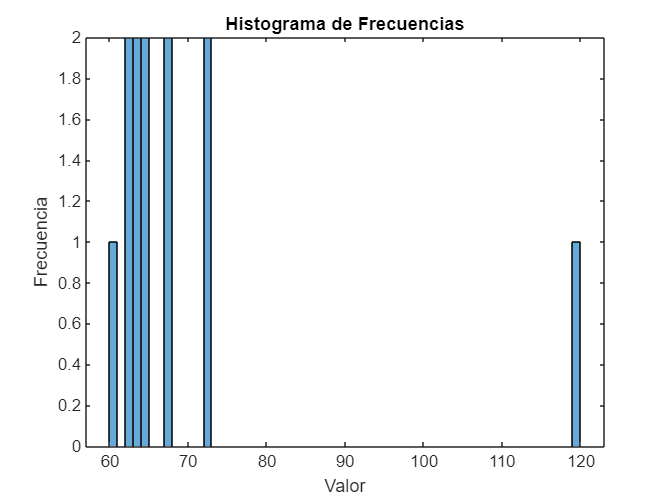

%histograma
histogram(data, [60:1:120])
title("Histograma de Frecuencias")
xlabel("Valor")
ylabel("Frecuencia")

%tabla de frecuencias
tab = tabulate(data);% Esta funcion tabula todos tus valores pero incluye desde 1 hasta tu valor maximo
min_tab = find(tab==min(data));%encuentra la posición del punto minimo en la variable tab.
array2table(tab(min_tab:end,:),'VariableNames',{'Valor','Frecuencia absoluta',...
'Frecuencia relativa (%)'})

ans = 61×3 table
    Valor    Frecuencia absoluta    Frecuencia relativa (%)
    _____    ___________________    _______________________

     60               1                     8.3333         
     61               0                          0         
     62               2                     16.667         
     63               2                     16.667         
     64               2                     16.667         
     65               0                          0         
     66               0                          0         
     67               2                     16.667         
     68               0                          0         
     69               0                          0         
     70               0                          0         
     71               0                          0         
     72               2                 